%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 155);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VIRTUAL_PROCESSOR_ID", "POSTED_INTR_NOTIFICATION_VECTOR", "EPTP_INDEX", "GUEST_ES_SELECTOR", "GUEST_CS_SELECTOR", "GUEST_SS_SELECTOR", "GUEST_DS_SELECTOR", "GUEST_FS_SELECTOR", "GUEST_GS_SELECTOR", "GUEST_LDTR_SELECTOR", "GUEST_TR_SELECTOR", "GUEST_INTR_STATUS", "GUEST_PML_INDEX", "HOST_ES_SELECTOR", "HOST_CS_SELECTOR", "HOST_SS_SELECTOR", "HOST_DS_SELECTOR", "HOST_FS_SELECTOR", "HOST_GS_SELECTOR", "HOST_TR_SELECTOR", "IO_BITMAP_A", "IO_BITMAP_B", "MSR_BITMAP", "VM_EXIT_MSR_STORE_ADDR", "VM_EXIT_MSR_LOAD_ADDR", "VM_ENTRY_MSR_LOAD_ADDR", "PML_ADDRESS", "TSC_OFFSET", "VIRTUAL_APIC_PAGE_ADDR", "APIC_ACCESS_ADDR", "PI_DESC_ADDR", "VM_FUNCTION_CONTROL", "EPT_POINTER", "EOI_EXIT_BITMAP0", "EPTP_LIST_ADDR", "VMREAD_BITMAP", "VMWRITE_BITMAP", "VIRT_EXCEPTION_INFO", "XSS_EXIT_BITMAP", "TSC_MULTIPLIER", "GUEST_PHYSICAL_ADDRESS", "VMCS_LINK_POINTER", "GUEST_IA32_DEBUGCTL", "GUEST_PAT", "GUEST_EFER", "GUEST_PERF_GLOBAL_CTRL", "GUEST_PDPTE0", "GUEST_BNDCFGS", "HOST_PAT", "HOST_EFER", "HOST_PERF_GLOBAL_CTRL", "PIN_BASED_VM_EXEC_CONTROL", "CPU_BASED_VM_EXEC_CONTROL", "EXCEPTION_BITMAP", "PAGE_FAULT_ERROR_CODE_MASK", "PAGE_FAULT_ERROR_CODE_MATCH", "CR3_TARGET_COUNT", "VM_EXIT_CONTROLS", "VM_EXIT_MSR_STORE_COUNT", "VM_EXIT_MSR_LOAD_COUNT", "VM_ENTRY_CONTROLS", "VM_ENTRY_MSR_LOAD_COUNT", "VM_ENTRY_INTR_INFO", "VM_ENTRY_EXCEPTION_ERROR_CODE", "VM_ENTRY_INSTRUCTION_LEN", "TPR_THRESHOLD", "SECONDARY_VM_EXEC_CONTROL", "PLE_GAP", "PLE_WINDOW", "VM_INSTRUCTION_ERROR", "VM_EXIT_REASON", "VM_EXIT_INTR_INFO", "VM_EXIT_INTR_ERROR_CODE", "IDT_VECTORING_INFO", "IDT_VECTORING_ERROR_CODE", "VM_EXIT_INSTRUCTION_LEN", "VMX_INSTRUCTION_INFO", "GUEST_ES_LIMIT", "GUEST_CS_LIMIT", "GUEST_SS_LIMIT", "GUEST_DS_LIMIT", "GUEST_FS_LIMIT", "GUEST_GS_LIMIT", "GUEST_LDTR_LIMIT", "GUEST_TR_LIMIT", "GUEST_GDTR_LIMIT", "GUEST_IDTR_LIMIT", "GUEST_ES_AR_BYTES", "GUEST_CS_AR_BYTES", "GUEST_SS_AR_BYTES", "GUEST_DS_AR_BYTES", "GUEST_FS_AR_BYTES", "GUEST_GS_AR_BYTES", "GUEST_LDTR_AR_BYTES", "GUEST_TR_AR_BYTES", "GUEST_INTERRUPTIBILITY_INFO", "GUEST_ACTIVITY_STATE", "GUEST_SMBASE", "GUEST_SYSENTER_CS", "GUEST_PREEMPTION_TIMER", "HOST_SYSENTER_CS", "CR0_GUEST_HOST_MASK", "CR4_GUEST_HOST_MASK", "CR0_READ_SHADOW", "CR4_READ_SHADOW", "CR3_TARGET_VALUE0", "EXIT_QUALIFICATION", "GUEST_LINEAR_ADDRESS", "GUEST_CR0", "GUEST_CR3", "GUEST_CR4", "GUEST_ES_BASE", "GUEST_CS_BASE", "GUEST_SS_BASE", "GUEST_DS_BASE", "GUEST_FS_BASE", "GUEST_GS_BASE", "GUEST_LDTR_BASE", "GUEST_TR_BASE", "GUEST_GDTR_BASE", "GUEST_IDTR_BASE", "GUEST_DR7", "GUEST_RSP", "GUEST_RIP", "GUEST_RFLAGS", "GUEST_PENDING_DBG_EXCEPTIONS", "GUEST_SYSENTER_ESP", "GUEST_SYSENTER_EIP", "HOST_CR0", "HOST_CR3", "HOST_CR4", "HOST_FS_BASE", "HOST_GS_BASE", "HOST_TR_BASE", "HOST_GDTR_BASE", "HOST_IDTR_BASE", "HOST_SYSENTER_ESP", "HOST_SYSENTER_EIP", "HOST_RSP", "HOST_RIP", "VarName141", "VarName142", "VarName143", "VarName144", "VarName145", "VarName146", "VarName147", "VarName148", "VarName149", "VarName150", "VarName151", "VarName152", "VarName153", "VarName154", "VIRTUAL_PROCESSOR_ID1"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
seedsmatrixmon = readtable("seeds_matrix_mon.csv", opts);


%Printing modes of CR0
field_cr0_guest_state_area=6800;
cr0_mon=categorical(seedsmatrixmon.GUEST_CR0);
indexes=find(cr0_mon~=categorical(0));

%translation in modes
[n,m]=size(seedsmatrixmon.GUEST_CR0)

n = 514220

m = 1

modes=zeros(size(seedsmatrixmon.GUEST_CR0));
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0x30')))=1;
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0x31')))=2;
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0x80000031')))=3;
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0x80050033')))=4;
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0x8005003b')))=5;
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0xc0050033')))=6;
modes(find(seedsmatrixmon.GUEST_CR0==hex2dec('0xc005003b')))=7;

%plot(indexes,cr0_mon(indexes), '*')
plot(find(modes>0),modes(find(modes>0)))
ylabels={'Mode1' 'Mode2' 'Mode3'  'Mode4' 'Mode5' 'Mode6' 'Mode7'}

ylabels = 1×7 cell array
    {'Mode1'}    {'Mode2'}    {'Mode3'}    {'Mode4'}    {'Mode5'}    {'Mode6'}    {'Mode7'}


set(gca,'yticklabel',ylabels);
%ylim({'48','3221553211'})
%xlim( [1 5000])
xlabel('VM exits');
ax = gca; 
ax.FontSize = 20;
ylim([0.5 7.5])
%[left, bottom, width, height] 
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
set(gca, 'YGrid', 'on', 'XGrid', 'on')
ax.GridAlpha = 0.3;
ax.Layer = 'top';
%[~, z] = zoomPlot(find(modes>0),modes(find(modes>0)), [250000 250010], [0.2 0.5 0.3 0.2]);
%hold(z, 'off');
%plot(find(modes>0),modes(find(modes>0)), '*');
[~, z] = zoomPlot(find(modes>0),modes(find(modes>0)), [250000 250010], [0.2 0.5 0.3 0.3]);
ylabels={'Mode1' ''  '' '' '' 'Mode2'}

ylabels = 1×6 cell array
    {'Mode1'}    {0×0 char}    {0×0 char}    {0×0 char}    {0×0 char}    {'Mode2'}


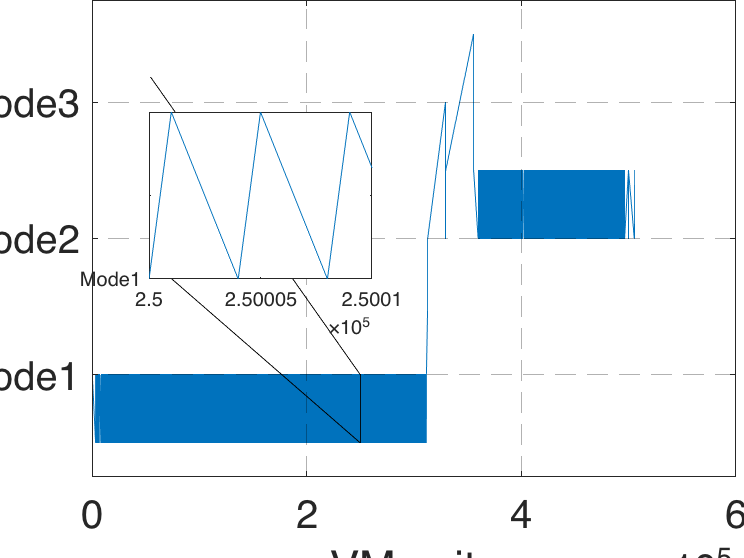

set(gca,'yticklabel',ylabels);


%save figure
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
a2 = gcf;
a2.PaperPositionMode = 'auto';
fig_pos = a2.PaperPosition;
a2.PaperSize = [fig_pos(3) fig_pos(4)];
print(a2, strcat(fileparts(pwd),'/figures/vmwrites_fitting_cr0.pdf'),'-dpdf','-r0');